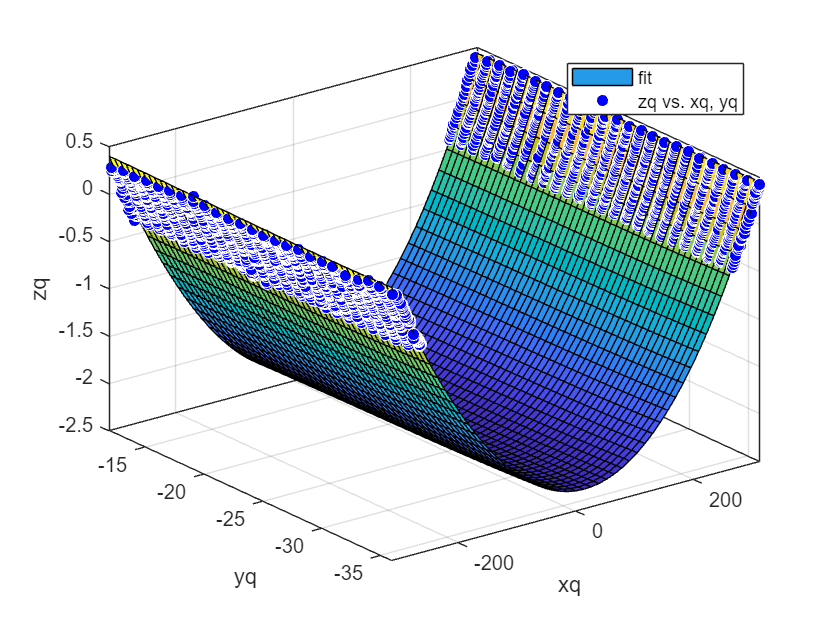

% X0 = (max(abs(xq))+min(abs(xq)))/2;
% idx = abs(A0(:,1)-X0)<=0.5;
% Y0 = A0(idx,2);
% Z0 = A0(idx,3);
% ZP = f(A0(idx,1),Y0);
% [xq, yq, zq] = PreprocessDate(ImpData,d);
% %% 拟合
% n = 3;%拟合方程次数
% [f1  gof] = createFit(xq, yq, zq, n);
% ZP1 = f1(A0(idx,1),Y0);
% plot(Y0,Z0,'o');
% hold on
% plot(Y0,ZP,'--*');
% hold on
% plot(Y0,ZP1,'--*');
% legend('点云轮廓y-z','4次拟合轮廓y-z','3次拟合轮廓y-z');


X0 = round((max(abs(xq))+min(abs(xq)))/2);
idx = abs(xq(:,1)-X0)<=0.5;
Y0 = yq(idx);
Z0 = zq(idx);
ZP = f(xq(idx,1),Y0);
[xq, yq, zq] = PreprocessDate(ImpData,d);
%% 拟合
n = 3;%拟合方程次数
[f1  gof] = createFit(xq, yq, zq, n);

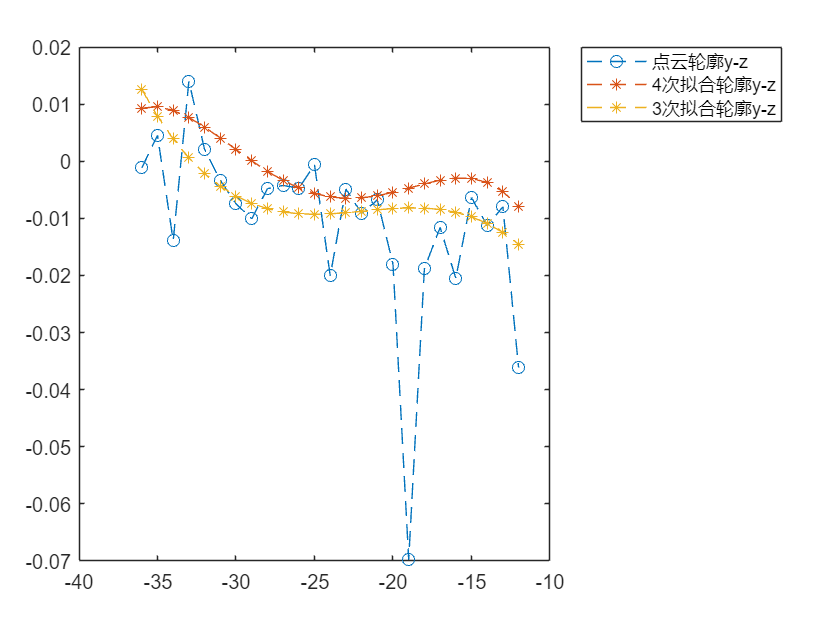

ZP1 = f1(xq(idx,1),Y0);
plot(Y0,Z0,'--o');
hold on
plot(Y0,ZP,'--*');
hold on
plot(Y0,ZP1,'--*');
legend('点云轮廓y-z','4次拟合轮廓y-z','3次拟合轮廓y-z');